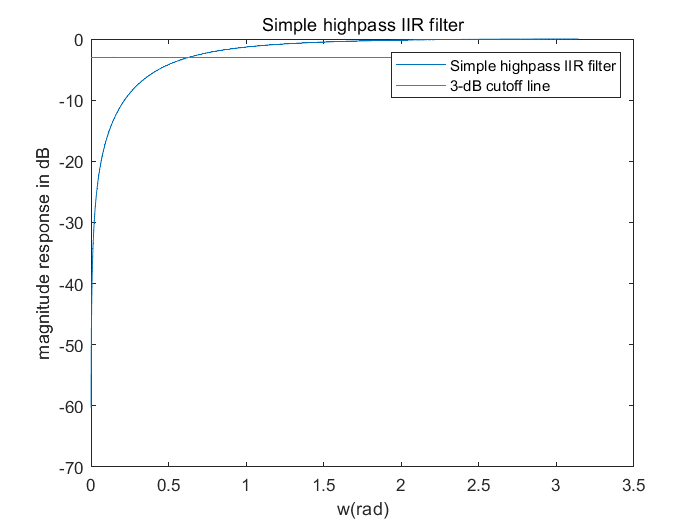

clear;
alpha = (1-sqrt(1-cos(0.2*pi)^2))/cos(0.2*pi);
w = linspace(0,pi,5000);
H = sqrt(((1+alpha)^2*(1-cos(w)))./(2*(1+alpha^2-2*alpha*cos(w))));
plot(w,20*log10(abs(H)));
hold on;
plot(w,-3*ones(1,5000));
xlabel('w(rad)'),ylabel('magnitude response in dB'),title('Simple highpass IIR filter');
legend('Simple highpass IIR filter','3-dB cutoff line');